clear;

fil1=transpose(load("BPNetwork1-FMP.txt")); %BP-filter brukt på I(t)
fil2=transpose(load("BPNetwork2-FMP.txt")); %BP-filter brukt på Q(t)

f1=fil1(1,:); Mag1=fil1(2,:); Phase1=fil1(3,:);
f2=fil2(1,:); Mag2=fil2(2,:); Phase2=fil2(3,:);

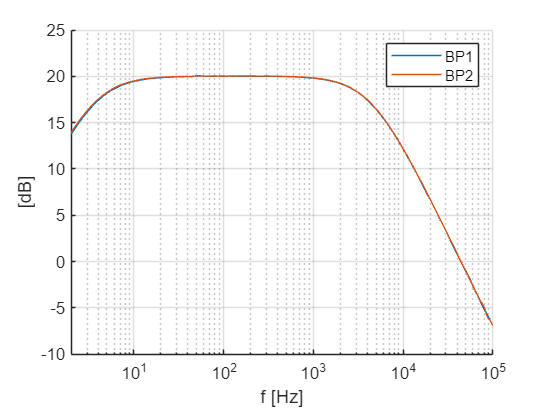

figure;
grid on;
ax = gca;
set(ax, 'XScale', 'log');
hold on;
plot(f1,Mag1);
plot(f2,Mag2);
hold off;
legend("BP1","BP2");
ylabel("[dB]");
xlabel("f [Hz]"); xlim([2 10^5]);